gridSize = 10;  % Example grid size (10x10)
% Random initial state
grid = randi([0 1], gridSize, gridSize); 

This generates the actual 10 by 10 **data** (cell states) in the grid, with values `0` and `1`.

- **0:** Represents a dead cell.

- **1:** Represents a live cell.

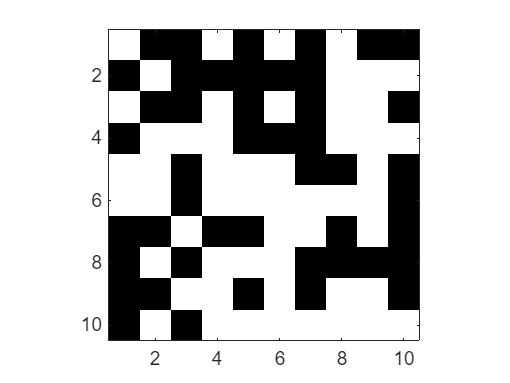


imagesc(grid); colormap(gray); axis equal tight;

This command visualizes a matrix `grid` as a grayscale image, where:

- The pixel sizes are equal and tightly fit the image dimensions.

- The grayscale color map ensures distinct visualization for binary states (`0 = black`, `1 = white`).

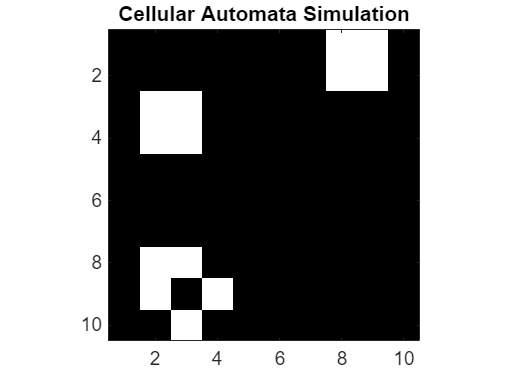

function liveNeighbors = countLiveNeighbors(grid, x, y)
    [rows, cols] = size(grid);
    neighbors = [-1 -1; -1 0; -1 1; 0 -1; 0 1; 1 -1; 1 0; 1 1];
    liveNeighbors = 0;
    
    for i = 1:size(neighbors, 1)
        nx = x + neighbors(i, 1);
        ny = y + neighbors(i, 2);

        % Wrap around edges (optional for toroidal grid)
        if nx < 1, nx = rows; elseif nx > rows, nx = 1; end
        if ny < 1, ny = cols; elseif ny > cols, ny = 1; end


        liveNeighbors = liveNeighbors + grid(nx, ny);
    end
end


function newGrid = updateGrid(grid)
    [rows, cols] = size(grid);
    newGrid = grid;

    for x = 1:rows
        for y = 1:cols
            liveNeighbors = countLiveNeighbors(grid, x, y);

            if grid(x, y) == 1  % Cell is alive
                if liveNeighbors < 2 || liveNeighbors > 3
                    newGrid(x, y) = 0;  % Cell dies
                end
            else  % Cell is dead
                if liveNeighbors == 3
                    newGrid(x, y) = 1;  % Cell becomes alive
                end
            end
        end
    end
end


function visualize(grid)
    imagesc(grid);
    colormap(gray);
    axis equal tight;
    title('Cellular Automata Simulation');
    drawnow;
end


clc; clear;

gridSize = 10;
grid = randi([0 1], gridSize, gridSize);

generations = 50;

for gen = 1:generations
    visualize(grid);
    grid = updateGrid(grid);
    pause(0.5);  % Pause for visualization speed
end
